clear all

#  EXTRAER ARCHIVOS

NxyzTABLE = readtable('Nxyz.xlsx','ReadRowNames',true);

NxyzTABLE.Properties.VariableNames{1} = 'X';
NxyzTABLE.Properties.VariableNames{2} = 'Y';
NxyzTABLE.Properties.VariableNames{3} = 'Z';


num_col = length(NxyzTABLE.Properties.RowNames);


%       CREAMOS TABLAS CON DATOS
xyz = NxyzTABLE{1:num_col,{'X','Y','Z'}}; %tabla con xyz
x_o = NxyzTABLE{1:num_col,{'X'}}; %separamos datos para graficar puntos
y_o = NxyzTABLE{1:num_col,{'Y'}};
z_o = NxyzTABLE{1:num_col,{'Z'}};



# DATOS PISTA

logitudPista=3020;
anchuraPista=30;
%   DATOS SUPERFICIE DE TRANSICION
FranjaAnchura=150;
FranjaLongitud=60;
pendienteTransicion=0.143;
altura=45;
%  DATOS DESPEGUE
LogitudBordeInteriorDespegue=180;
DivergenciaDespegue=0.125;
logitudTotal=6480;
pendienteDespegue=0.02;

logitudTotal2=8520;

%   DATOS APROX
LogitudBordeInteriorAprox=300;
DivergenciaAprox=0.15;
LongitudPrimeraSeccion=3000;
pendienteAproximacion=0.02;


LongitudSegundaSeccion=3600;
pendienteAproximacion2=0.025;

LongitudTerceraSeccion=8600;

np=50; %puntos para piramides



## Creamos figura pista

XXpista = [0,0,0,0,logitudPista,logitudPista,logitudPista,logitudPista]';
YYpista = [anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2,anchuraPista/2,anchuraPista/2,-anchuraPista/2,-anchuraPista/2]';
ZZpista = [0,1,0,1,0,1,0,1]';
Figurapista = alphaShape(XXpista,YYpista,ZZpista); %cramos la figura


## CREAMOS SUPERFICIE DE TRANSICION

% estas son las aristas de nuestro volumen
 XXtrans = [-FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),-FranjaLongitud,...
    -FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud+altura/pendienteTransicion,...
    logitudPista+FranjaLongitud+altura/pendienteTransicion]';
YYtrans = [FranjaAnchura,-FranjaAnchura,-FranjaAnchura,+FranjaAnchura,...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion)),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),...
    -(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion))]';
ZZtrans = [0,0,0,0,altura,altura,altura,altura,altura,altura,altura,altura]';

Figuratrans = alphaShape(XXtrans,YYtrans,ZZtrans); %cramos la figura

%TRANS 2
XXtrans2 = [-FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    -FranjaLongitud,-FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud]';
YYtrans2 = [FranjaAnchura,-FranjaAnchura,-FranjaAnchura,+FranjaAnchura,...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura),...
    altura/pendienteTransicion+FranjaAnchura,-(altura/pendienteTransicion+FranjaAnchura)]';
ZZtrans2 = [0,0,0,0,altura,altura,altura,altura]';

Figuratrans2 = alphaShape(XXtrans2,YYtrans2,ZZtrans2);

%TRANS 3 
XXtrans3 = [-FranjaLongitud,-FranjaLongitud,...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),...
    -(altura/pendienteTransicion+FranjaLongitud),-(altura/pendienteTransicion+FranjaLongitud),]';
YYtrans3 = [FranjaAnchura,-FranjaAnchura,...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion)),...
    FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaAprox*(altura/pendienteTransicion))]';
ZZtrans3= [0,0,altura,altura,0,0]';

Figuratrans3 = alphaShape(XXtrans3,YYtrans3,ZZtrans3);

%TRANS 4
XXtrans4 = [logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,...
    logitudPista+FranjaLongitud+altura/pendienteTransicion,logitudPista+FranjaLongitud+altura/pendienteTransicion...
    logitudPista+FranjaLongitud+altura/pendienteTransicion,logitudPista+FranjaLongitud+altura/pendienteTransicion]';
YYtrans4 = [FranjaAnchura,-FranjaAnchura,...
    FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion)),...
    FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion),-(FranjaAnchura+DivergenciaDespegue*(altura/pendienteTransicion)),]';
ZZtrans4 = [0,0,altura,altura,0,0]';

Figuratrans4 = alphaShape(XXtrans4,YYtrans4,ZZtrans4);




#### MIRAR SI ESTA EN SUPERCICIE TRANS i TRANS 2, TRANS 3

%mirar si es dentro o fuera (figura,puntos)
%EstaEnTRANS = inShape(Figuratrans,xyz) 

for d=1:1:length(xyz) %para cada obstaculo
    
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);%Busca puntos de la piramide con verize obstaculo
    EstaEnTRANS_P = inShape(Figuratrans,x_p,y_p,z_p);%misra si estan dentro
    
    if mean(EstaEnTRANS_P)>0%debuele 1 o 0 si estan dentro o fuera
        EstaEnTRANS(d) = 1;
    else
        EstaEnTRANS(d) = 0;
    end
    
end
EstaEnTRANS=EstaEnTRANS'

EstaEnTRANS =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




%EstaEnTRANS2 = inShape(Figuratrans2,xyz);
for d=1:1:length(xyz)
    
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnTRANS2_P = inShape(Figuratrans2,x_p,y_p,z_p);
    
    if mean(EstaEnTRANS2_P)>0
        EstaEnTRANS2(d) = 1;
    else
        EstaEnTRANS2(d) = 0;
    end
    
end
EstaEnTRANS2=EstaEnTRANS2'

EstaEnTRANS2 =      0
     0
     1
     0
     0
     0
     0
     0
     0
     0





%EstaEnTRANS3 = inShape(Figuratrans3,xyz);
for d=1:1:length(xyz)
    
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnTRANS3_P = inShape(Figuratrans3,x_p,y_p,z_p);
    
    if mean(EstaEnTRANS3_P)>0
        EstaEnTRANS3(d) = 1;
    else
        EstaEnTRANS3(d) = 0;
    end
    
end
EstaEnTRANS3=EstaEnTRANS3'

EstaEnTRANS3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




%EstaEnTRANS4 = inShape(Figuratrans4,xyz);
for d=1:1:length(xyz)
    
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnTRANS4_P = inShape(Figuratrans4,x_p,y_p,z_p);
    
    if mean(EstaEnTRANS4_P)>0
        EstaEnTRANS4(d) = 1;
    else
        EstaEnTRANS4(d) = 0;
    end
    
end
EstaEnTRANS4=EstaEnTRANS4'

EstaEnTRANS4 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## CREAMOS SUPERFICIE DE APROXIMACION

% estas son las aristas de nuestro volumen
XXaprox = [-(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud),-FranjaLongitud,-FranjaLongitud,...
    -(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud)]';
YYaprox = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,-(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion),...
    -FranjaAnchura,FranjaAnchura,FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion)]';
ZZaprox = [0,0,0,0,pendienteAproximacion*LongitudPrimeraSeccion,pendienteAproximacion*LongitudPrimeraSeccion]';

FiguraAprox = alphaShape(XXaprox,YYaprox,ZZaprox); %cramos la figura


APPROX 2

XXaprox2 = [-(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud),...
    -(LongitudPrimeraSeccion+FranjaLongitud),-(LongitudPrimeraSeccion+FranjaLongitud)...
    -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),...
    -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion)]';

YYaprox2 = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,-(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion),...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion)...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...
    FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
    -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion)]';

ZZaprox2 = [0,0,pendienteAproximacion*LongitudPrimeraSeccion,pendienteAproximacion*LongitudPrimeraSeccion...  
    0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
    pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion]';

FiguraAprox2 = alphaShape(XXaprox2,YYaprox2,ZZaprox2); %cramos la figura


APPROX 3

XXaprox3 = [-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion),-(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion)...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion),...
            -(LongitudPrimeraSeccion+FranjaLongitud+LongitudSegundaSeccion+LongitudTerceraSeccion)]';

YYaprox3 = [FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
             -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion,...
            -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion),...    
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion,...
             -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion),...
            FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion,...
            -(FranjaAnchura+DivergenciaAprox*LongitudPrimeraSeccion+DivergenciaAprox*LongitudSegundaSeccion+DivergenciaAprox*LongitudTerceraSeccion)]';


ZZaprox3 = [0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
            pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion...
            0,0,pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion,...
            pendienteAproximacion2*LongitudSegundaSeccion+pendienteAproximacion*LongitudPrimeraSeccion]';

FiguraAprox3 = alphaShape(XXaprox3,YYaprox3,ZZaprox3); %cramos la figura


####  MIRAR SI ESTA EN SUPERCICIE APROXIMACION

%mirar si es dentro o fuera (figura,puntos)
%EstaEnAPROX = inShape(FiguraAprox,xyz); 
for d=1:1:length(xyz)
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnAPROX_P = inShape(FiguraAprox,x_p,y_p,z_p);
    if mean(EstaEnAPROX_P)>0
        EstaEnAPROX(d) = 1;
    else
        EstaEnAPROX(d) = 0;
    end
end
EstaEnAPROX=EstaEnAPROX'

EstaEnAPROX =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




%EstaEnAPROX2 = inShape(FiguraAprox2,xyz); 
for d=1:1:length(xyz)
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnAPROX2_P = inShape(FiguraAprox2,x_p,y_p,z_p);
    if mean(EstaEnAPROX2_P)>0
        EstaEnAPROX2(d) = 1;
    else
        EstaEnAPROX2(d) = 0;
    end
end
EstaEnAPROX2=EstaEnAPROX2'

EstaEnAPROX2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




%EstaEnAPROX3 = inShape(FiguraAprox3,xyz);
for d=1:1:length(xyz)
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnAPROX3_P = inShape(FiguraAprox3,x_p,y_p,z_p);
    if mean(EstaEnAPROX3_P)>0
        EstaEnAPROX3(d) = 1;
    else
        EstaEnAPROX3(d) = 0;
    end
end
EstaEnAPROX3=EstaEnAPROX3'

EstaEnAPROX3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


## CREAMOS SUPERFICIE DE DESPEGUE

% estas son las aristas de nuestro volumen
XXdespegue = [logitudPista+FranjaLongitud,logitudPista+FranjaLongitud,logitudPista+FranjaLongitud+logitudTotal,...
    logitudPista+FranjaLongitud+logitudTotal,logitudPista+FranjaLongitud+logitudTotal,...
    logitudPista+FranjaLongitud+logitudTotal]';

YYdespegue = [FranjaAnchura,-FranjaAnchura,-(FranjaAnchura+DivergenciaDespegue*logitudTotal),...
    FranjaAnchura+DivergenciaDespegue*logitudTotal,-(FranjaAnchura+DivergenciaDespegue*logitudTotal),...
    FranjaAnchura+DivergenciaDespegue*logitudTotal]';

ZZdespegue = [0,0,0,0,pendienteDespegue*logitudTotal,pendienteDespegue*logitudTotal]';

FiguraDespegue = alphaShape(XXdespegue,YYdespegue,ZZdespegue); %cramos la figura




#### MIRAR SI ESTA EN SUPERCICIE DESPEGUE

%mirar si es dentro o fuera (figura,puntos)
%EstaEnDESPEGUE = inShape(FiguraDespegue,xyz); 

for d=1:1:length(xyz)
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnDESPEGUE_P = inShape(FiguraDespegue,x_p,y_p,z_p);
    
    if mean(EstaEnDESPEGUE_P)>0
        EstaEnDESPEGUE(d) = 1;
    else
        EstaEnDESPEGUE(d) = 0;
    end
end
EstaEnDESPEGUE=EstaEnDESPEGUE'

EstaEnDESPEGUE =      0
     1
     0
     1
     0
     1
     0
     0
     0
     0


#### CREAMOS SUPERFICIE DE CONO 


h = 0:1:100;

theta=linspace(0,2*pi,50);
vec_x=[];
vec_y=[];
vec_z=[];

for i= 1:1:length(h) %para cada altura
    
    radius=0:150:(20*h(i)+4000);
    
    for t=1:1:length(radius)
       x=radius(t)*cos(theta);
       y=radius(t)*sin(theta);
       z=ones(1,length(theta))*h(i);
       vec_x= [vec_x x];
       vec_y= [vec_y y];
       vec_z= [vec_z z];
       
    end
end

 
FiguraCono = alphaShape((vec_x+logitudPista/2)',vec_y',(vec_z+45)');

#### MIRAR SI ESTA EN SUPERCICIE CONO


%EstaEnCONO = inShape(FiguraCono,xyz);

for d=1:1:length(xyz)
    [x_p,y_p,z_p] = piramiade(xyz(d,:),1400,np);
    EstaEnCONO_P = inShape(FiguraCono,x_p,y_p,z_p);
    
    if mean(EstaEnCONO_P)>0
        EstaEnCONO(d) = 1;
    else
        EstaEnCONO(d) = 0;
    end
end
EstaEnCONO=EstaEnCONO'

EstaEnCONO =      1
     0
     1
     1
     0
     0
     0
     0
     0
     0


#    DATOS EN TABLA

InorOuttableTRANS = table(EstaEnTRANS); %converir logicos a tabla
tablaconTRANS = [NxyzTABLE InorOuttableTRANS]; %juntar tablas

InorOuttableTRANS2 = table(EstaEnTRANS2); %converir logicos a tabla
tablaconTRANS2 = [tablaconTRANS InorOuttableTRANS2]; %juntar tablas

InorOuttableTRANS3 = table(EstaEnTRANS3);
tablaconTRANS3 = [tablaconTRANS2, InorOuttableTRANS3];

InorOuttableTRANS4 = table(EstaEnTRANS4);
tablaconTRANS4 = [tablaconTRANS3, InorOuttableTRANS4];

InorOuttableAPROX = table(EstaEnAPROX); %converir logicos a tabla
tablaconTRANSiAPROX = [tablaconTRANS4 InorOuttableAPROX]; %juntar tablas

InorOuttableAPROX2 = table(EstaEnAPROX2); %converir logicos a tabla
tablaconTRANSiAPROX2 = [tablaconTRANSiAPROX InorOuttableAPROX2]; %juntar tablas

InorOuttableAPROX3 = table(EstaEnAPROX3); %converir logicos a tabla
tablaconTRANSiAPROX3 = [tablaconTRANSiAPROX2 InorOuttableAPROX3]; %juntar tablas

InorOuttableDESPEGUE = table(EstaEnDESPEGUE); %converir logicos a tabla
tablaconTRANSiAPROXiDESPEGUE = [tablaconTRANSiAPROX3 InorOuttableDESPEGUE]; %juntar tablas


InorOuttableCONO = table(EstaEnCONO); %converir logicos a tabla
tablaconTRANSiAPROXiDESPEGUECONO = [tablaconTRANSiAPROXiDESPEGUE InorOuttableCONO]; %juntar tablas


%       COMPARAMOS TABLA
c3= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnDESPEGUE'};
c2= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnAPROX'};
c22=tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnAPROX2'};
c23=tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnAPROX3'};
c1= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS'};
c4= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS2'};
c5= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS3'};
c6= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnTRANS4'};
c7= tablaconTRANSiAPROXiDESPEGUECONO{:,'EstaEnCONO'};

ESTADENTROALGUNAZONA= c1+c2+c3+c4+c5+c6+c7+c22+c23; % sumamos todos
InorOuttableRESULT = table(ESTADENTROALGUNAZONA); %converir logicos a tabla
tablaFINAL = [tablaconTRANSiAPROXiDESPEGUECONO InorOuttableRESULT]

tablaFINAL = 24×13 table
                                 X        Y       Z     EstaEnTRANS    EstaEnTRANS2    EstaEnTRANS3    EstaEnTRANS4    EstaEnAPROX    EstaEnAPROX2    EstaEnAPROX3    EstaEnDESPEGUE    EstaEnCONO    ESTADENTROALGUNAZONA
                               _____    _____    ___    ___________    ____________    ____________    ____________    ___________    ____________    ____________    ______________    __________    ____________________

    LVDA - MT - 0001 - 2021     4160      920    179         0              0

RESULTlogic = logical(ESTADENTROALGUNAZONA);


%for para pintar en fuincion si dentro o no
sz = size(RESULTlogic);
for ii = 1:sz
      if RESULTlogic(ii) == 0
          f = 'o';
          c = 'Color';
          m = [0, 0, 255] / 255;
      else
          f = 'x';
          c = 'Color';
          m = [255, 0, 0] / 255;
      end
      plot3(x_o(ii),y_o(ii),z_o(ii),f,c,m,'MarkerSize', 10, 'LineWidth', 3) %plot de puntos obstaculos
      hold on
end
      %pintamos piramide
for k=1:1:length(xyz)
      [x_p,y_p,z_p] = piramiade(xyz(k,:),1400,np);
      PR = alphaShape(x_p,y_p,z_p);
      plot(PR,'EdgeAlpha',0.1,'FaceColor',"#40ed6e",'FaceAlpha',0.5);
end


%   contador de obstaculos:
counter = 0;
for ii = 1:sz
    if RESULTlogic(ii) == 0
        counter = counter + 0;
    else
        counter= counter+1;
    end
end
X = ['Número de obstáculos que pinchan nuestras zonas: ', num2str(counter), '.'];
disp(X)

Número de obstáculos que pinchan nuestras zonas: 15.


# %       CREAMOS ARCHIVO CON LOS NUEVOS DATOS


%NxyzTABLE = readtable('Nxyz.xlsx','ReadRowNames',true);

filename = 'NxyzFINAL.xlsx';

if exist('NxyzFINAL.xlsx')
    
    delete("NxyzFINAL.xlsx");
    writetable(tablaFINAL,filename);
    
else
    writetable(tablaFINAL,filename);
    
end




# PLOTS de FIGURAS

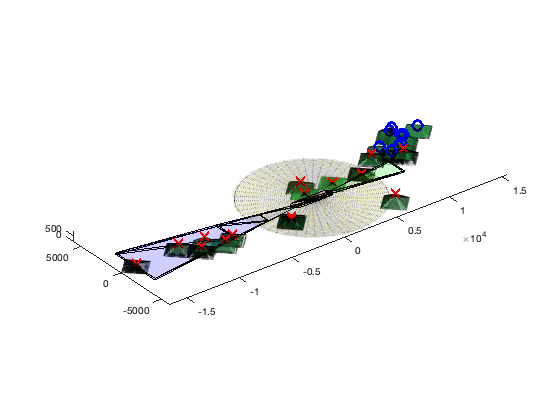



hold on %tener dos O MAS graficas en mismos ejes
plot(Figurapista,'FaceColor','black','FaceAlpha',1); %plot de pista

plot(Figuratrans,'FaceColor','red','FaceAlpha',0.1); %plot de trans
plot(Figuratrans2,'FaceColor','red','FaceAlpha',0.1); %plot de trans2
plot(Figuratrans3,'FaceColor','red','FaceAlpha',0.1); %plot de trans3
plot(Figuratrans4, 'FaceColor','red', 'FaceAlpha',0.1); %plot de trans4
% 
plot(FiguraAprox,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox
plot(FiguraAprox2,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox
plot(FiguraAprox3,'FaceColor','blue','FaceAlpha',0.1); %plot de aprox
% 
plot(FiguraDespegue,'FaceColor','green','FaceAlpha',0.1); %plot de despegue
plot(FiguraCono, 'FaceColor',"yellow", 'FaceAlpha',0.1, "EdgeAlpha",0.05)%plot de cono


hold off

function [x,y,z] = piramiade(xyz_punto,a,np) % a = gordura de piramide, np puntos de piraminde
        
    x=[];
    y=[];
    z=[];
    
    x(1)=xyz_punto(1);
    y(1)=xyz_punto(2);
    z(1)=xyz_punto(3);
    
    z_vec = linspace(0,z(1),np);
    a = linspace(a,0,np);
 
for h = 1:1:np

    larg=length(x);
    
    x(larg+1)=xyz_punto(1);
    y(larg+1)=xyz_punto(2)+a(h);
    z(larg+1)=z_vec(h);
    
    x(larg+2)=xyz_punto(1);
    y(larg+2)=xyz_punto(2)-a(h);
    z(larg+2)=z_vec(h);
    
    x(larg+3)=xyz_punto(1)+a(h);
    y(larg+3)=xyz_punto(2);
    z(larg+3)=z_vec(h);
      
    x(larg+4)=xyz_punto(1)-a(h);
    y(larg+4)=xyz_punto(2);
    z(larg+4)=z_vec(h);
    
end

    x=x';
    y=y';
    z=z';
    
end
